clear
load('pi_vector1.mat')
name = strings(210,1);
for i = 1:21
    for j = 1:10
        formatname = '%02d%02d';
        name((i-1)*10+j) = sprintf(formatname,i,j);
    end
end


## k-means Clustering - 5


% number of times of clustering
N = 1000; 
C5 = 5;

% upper triangular frequency matrix
F5 = zeros(length(pi(:,1)));
for n = 1:N
    result = kmeans(pi,C5);
    for i = 1:length(F5)-1
        for j = i+1:length(F5)
            if result(i) == result(j)
                F5(i,j) = F5(i,j)+1; % number of times two samples clustered together
            end
        end
    end
end

% normalize
Max = max(F5,[],'all');
F5 = F5./Max;


## Hierarchical Clustering

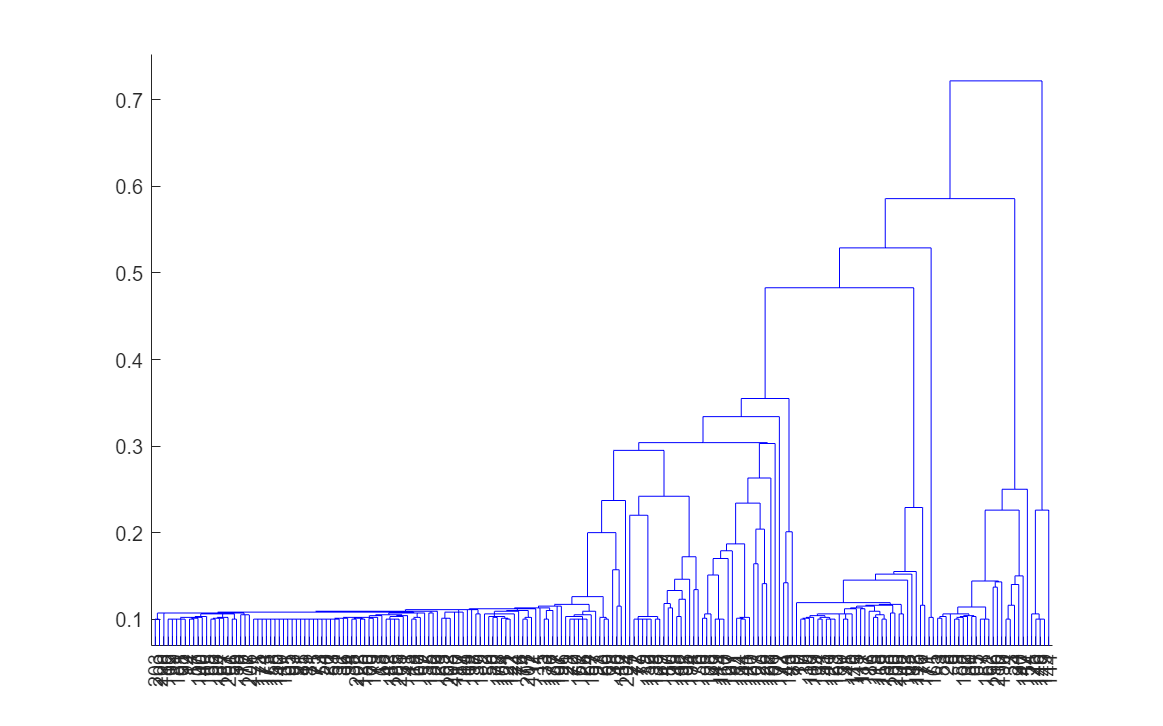


Dmatrix5 = 1.1-F5;
for i = 1:length(Dmatrix5)
    for j = i+1:length(Dmatrix5)
        Dmatrix5(j,i) = Dmatrix5(i,j);
    end
    Dmatrix5(i,i) = 0;
end
D5 = squareform(Dmatrix5,'tovector');
Z5 = linkage(D5);
figure(500)
dendrogram(Z5,0)

## Remove outliers (#1)


% claim outliers
out1 = [149 148 146 144 25];
namere1 = name;
pire1 = pi;
for i = 1:length(out1)
    s = strcat('sample: ', namere1(out1(i)));
    pire1(out1(i),:) = [];
    namere1(out1(i),:) = [];
    disp(s);
end

sample:1509
sample:1508
sample:1506
sample:1504
sample:0305


## k-means Clustering - 5


% upper triangular frequency matrix
F5re1 = zeros(length(pire1(:,1)));
for n = 1:N
    result = kmeans(pire1,C5);
    for i = 1:length(F5re1)-1
        for j = i+1:length(F5re1)
            if result(i) == result(j)
                F5re1(i,j) = F5re1(i,j)+1; % number of times two samples clustered together
            end
        end
    end
end

% normalize
Max = max(F5re1,[],'all');
F5re1 = F5re1./Max;


## Hierarchical Clustering

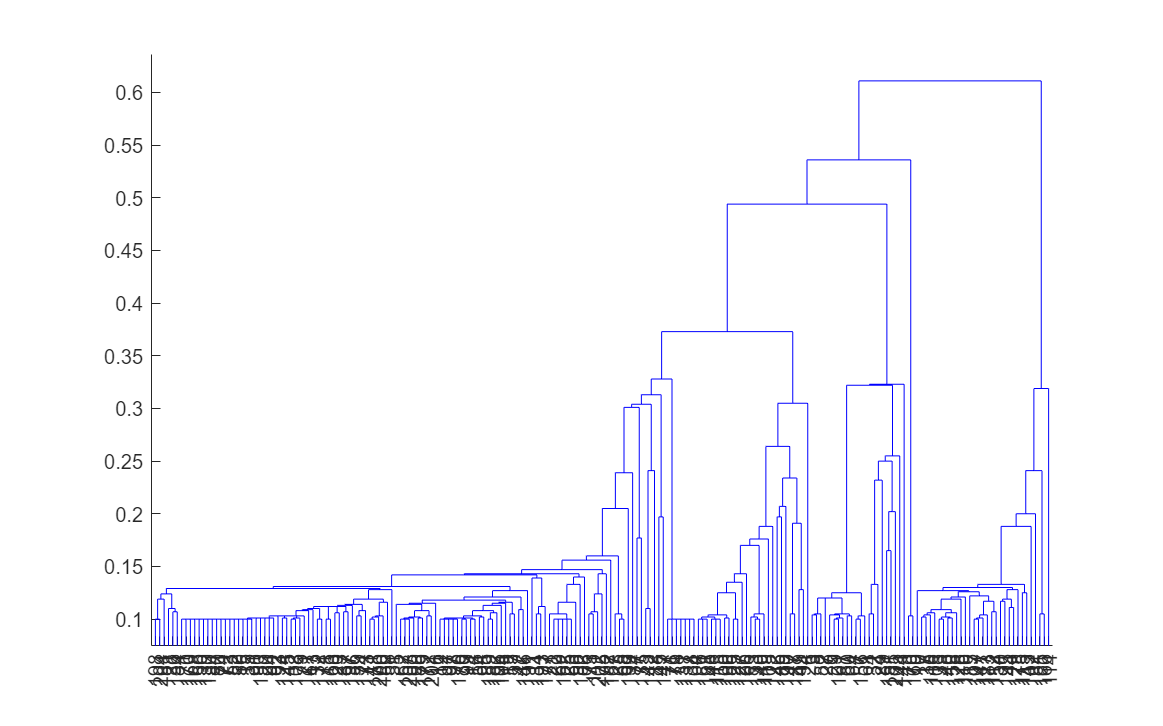

Dmatrix5re1 = 1.1-F5re1;
for i = 1:length(Dmatrix5re1)
    for j = i+1:length(Dmatrix5re1)
        Dmatrix5re1(j,i) = Dmatrix5re1(i,j);
    end
    Dmatrix5re1(i,i) = 0;
end
D5re1 = squareform(Dmatrix5re1,'tovector');
Z5re1 = linkage(D5re1);
figure(501)
dendrogram(Z5re1,0)

## Remove outliers (#2)


% claim three outliers
out2 = [160 70]

out2 =    160    70


namere2 = namere1;
pire2 = pire1;
for i = 1:length(out2)
    s = strcat('sample: ', namere2(out2(i)));
    pire2(out2(i),:) = [];
    namere2(out2(i),:) = [];
    disp(s);
end

sample:1705
sample:0801


## k-means Clustering - 5

% upper triangular frequency matrix
F5re2 = zeros(length(pire2(:,1)));
for n = 1:N
    result = kmeans(pire2,C5);
    for i = 1:length(F5re2)-1
        for j = i+1:length(F5re2)
            if result(i) == result(j)
                F5re2(i,j) = F5re2(i,j)+1; % number of times two samples clustered together
            end
        end
    end
end

% normalize
Max = max(F5re2,[],'all');
F5re2 = F5re2./Max;


## Hierarchical Clustering

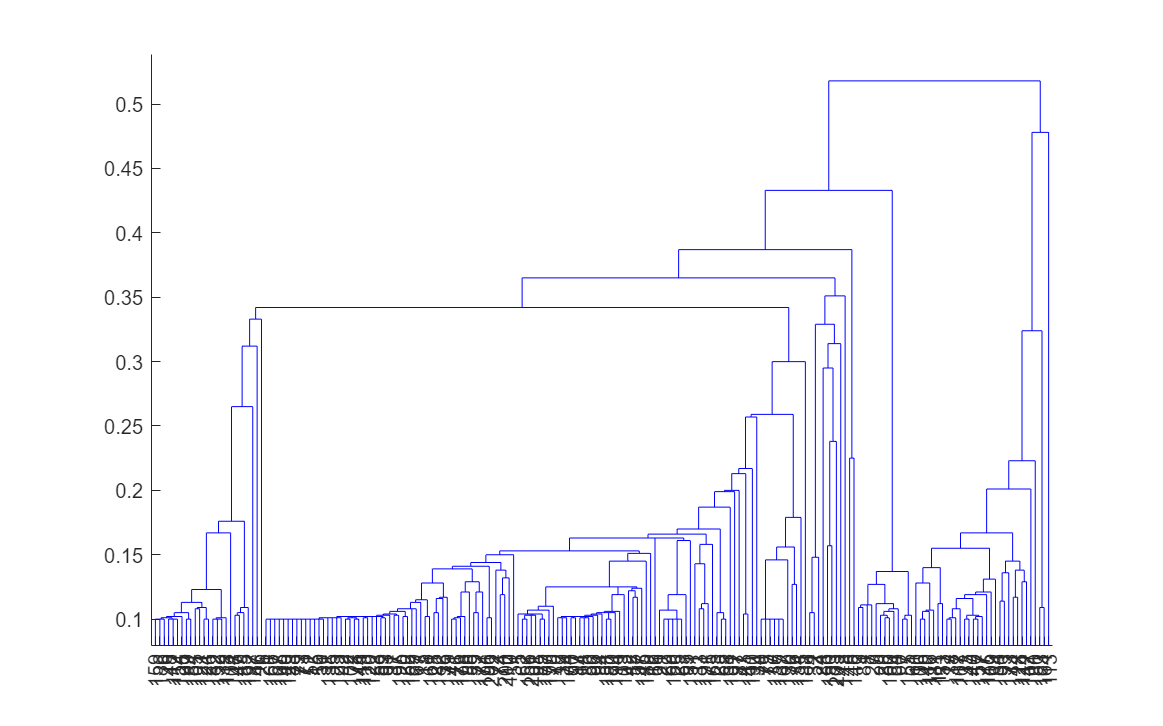

Dmatrix5re2 = 1.1-F5re2;
for i = 1:length(Dmatrix5re2)
    for j = i+1:length(Dmatrix5re2)
        Dmatrix5re2(j,i) = Dmatrix5re2(i,j);
    end
    Dmatrix5re2(i,i) = 0;
end
D5re2 = squareform(Dmatrix5re2,'tovector');
Z5re2 = linkage(D5re2);
figure(502)
dendrogram(Z5re2,0)

## Remove outliers (#3)


% claim three outliers
out3 = [164 163 146 113 45];
namefi = namere2;
pifi = pire2;
for i = 1:length(out3)
    s = strcat('sample: ', namefi(out3(i)));
    pifi(out3(i),:) = [];
    namefi(out3(i),:) = [];
    disp(s);
end

sample:1801
sample:1710
sample:1602
sample:1205
sample:0506


## k-means Clustering - 5

% upper triangular frequency matrix
F5fi = zeros(length(pifi(:,1)));
for n = 1:N
    result = kmeans(pifi,C5);
    for i = 1:length(F5fi)-1
        for j = i+1:length(F5fi)
            if result(i) == result(j)
                F5fi(i,j) = F5fi(i,j)+1; % number of times two samples clustered together
            end
        end
    end
end

% normalize
Max = max(F5fi,[],'all');
F5fi = F5fi./Max;


## Hierarchical Clustering(final)

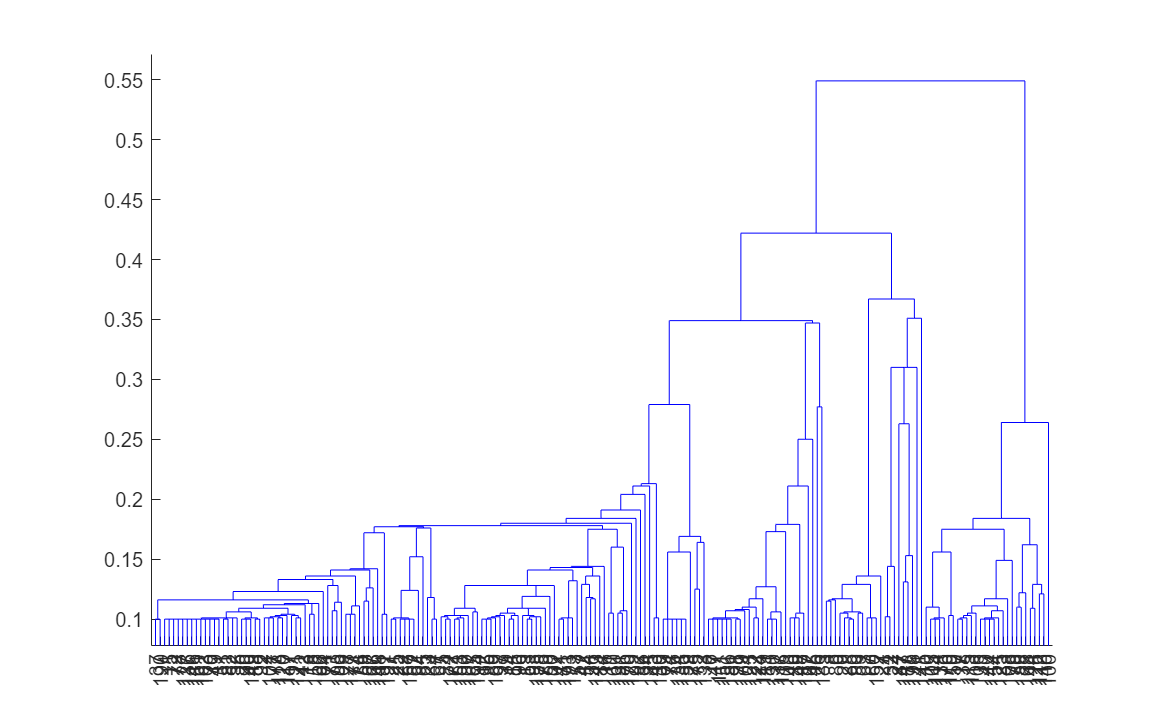

Dmatrix5fi = 1.1-F5fi;
for i = 1:length(Dmatrix5fi)
    for j = i+1:length(Dmatrix5fi)
        Dmatrix5fi(j,i) = Dmatrix5fi(i,j);
    end
    Dmatrix5fi(i,i) = 0;
end
D5fi = squareform(Dmatrix5fi,'tovector');
Z5fi = linkage(D5fi);
figure(1000)
dendrogram(Z5fi,0)

## Save


namecell = cellstr(namefi);
save('datah1.mat','F5fi','namecell')

## Analysis

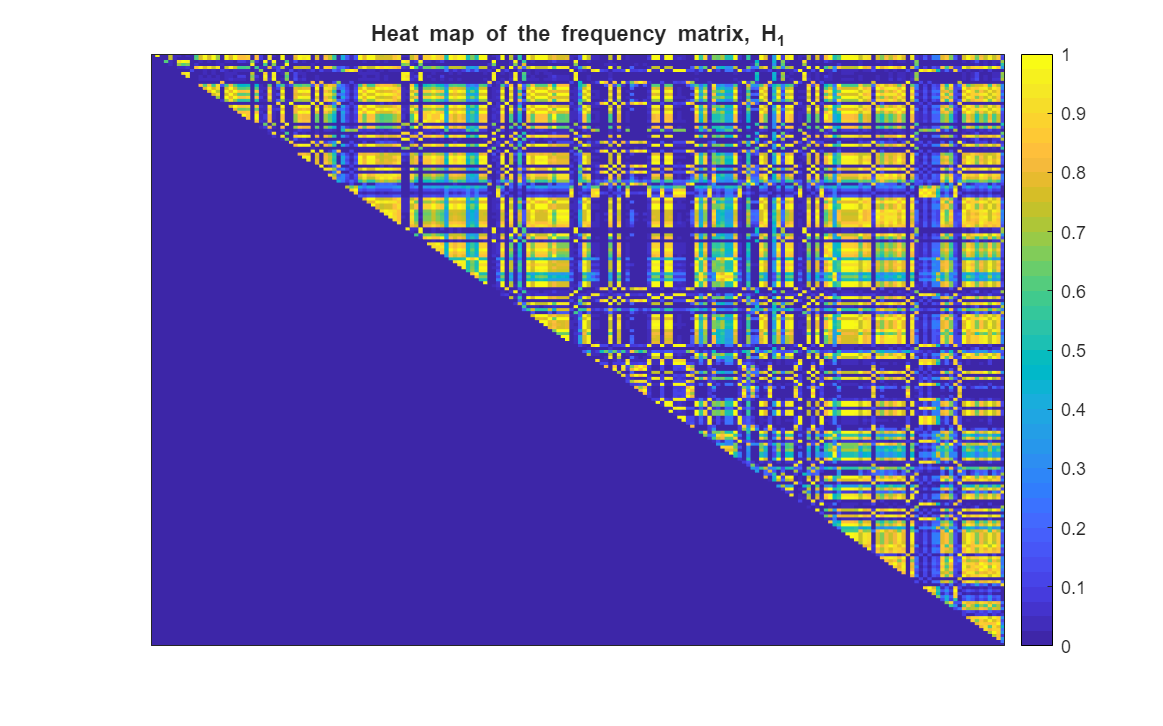

% 
% most correlated samples
[row,col] = find(F5fi == 1);
figure(999)
heatmap(F5fi,'Colormap',parula(40))
Ax = gca;
Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
grid off
title('Heat map of the frequency matrix, H_1')

## PCA

pi = pifi;
[coeff,score,latent] = pca(pi');
S = length(pi(:,1))

S = 198

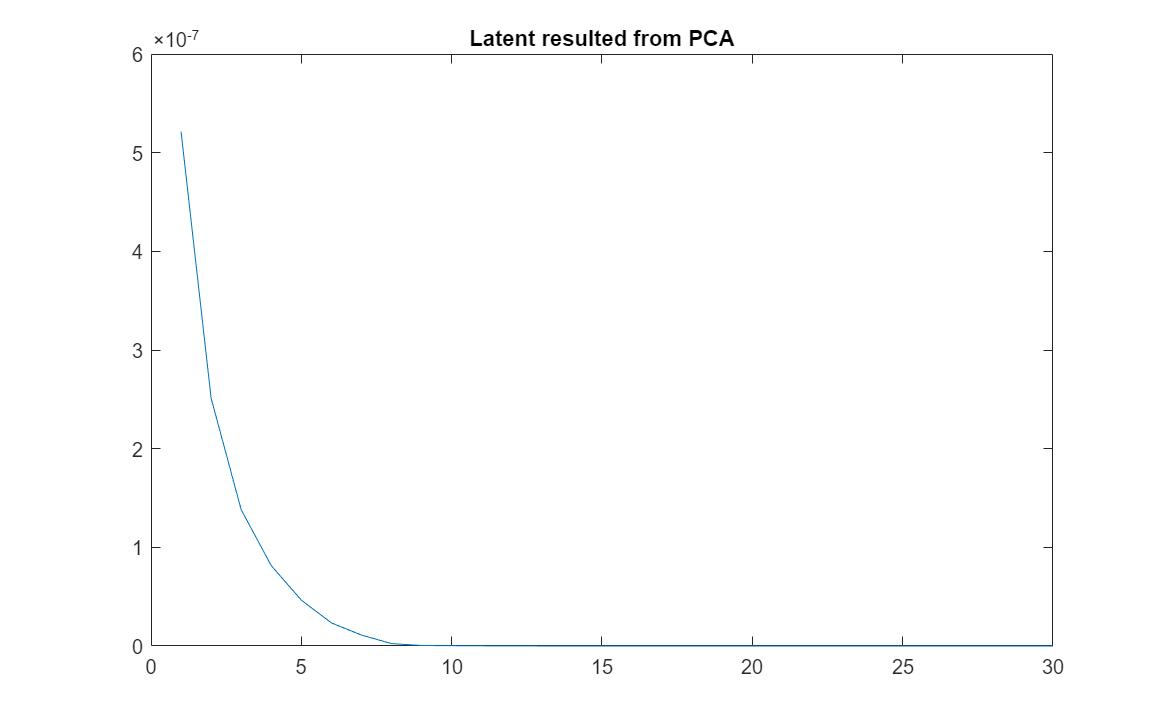

ncomp = 20; % number of component used
proj = zeros(S,ncomp);
for i = 1:S
    for j = 1:ncomp
        proj(i,j) = coeff(i,j);
    end
end
save('pcah1.mat','proj','pi')
L = sum(latent);
latentx = 1:S;
latenty = latent;
for i = 1:S
    latenty(i) = L - sum(latent(1:i));
end
plot(latentx,latenty)
xlim([0 30])
title('Latent resulted from PCA')